# Midterm Question #

**Author: Keith Chester**

**E-mail: kchester@wpi.edu**

## Methods

We will be looking at solving the Jacobian for the following robot:

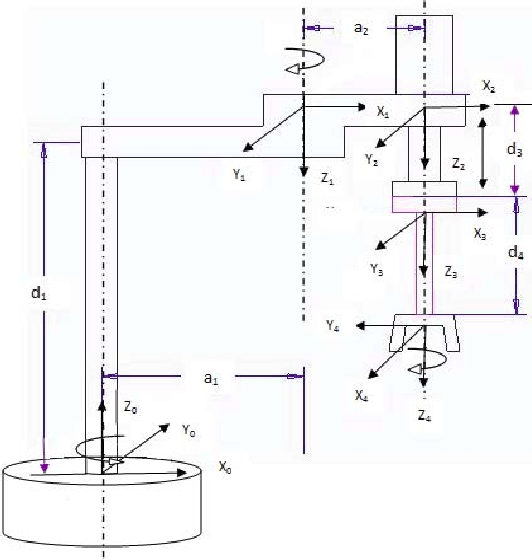

To do this, we will first make use of the axis, which thankfully follow standard DH convention, and make a DH table for them. We also create symbolic values to work our algebra with when trying to solve for the Jacobian.

syms phi theta a1 a2 d1 d3 d4

dh_table = {
    [phi     d1  a1      pi],
    [theta   0   a2      0 ],
    [0       d3  0       0 ],
    [0       d4  0       0 ],
}

dh_table = 4×1 cell array
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}
    {1×4 sym}


Using the DH table, we can generate transformation matricies for each link. We can see them here:

A1 = transform_from_dh_row(dh_table, 1, true)

$$A1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 = transform_from_dh_row(dh_table, 2, true)

$$A2 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & a_{2}\,\cos\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & a_{2}\,\sin\left(\theta \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 = transform_from_dh_row(dh_table, 3, true)

$$A3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 = transform_from_dh_row(dh_table, 4, true)

$$A4 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

We need, however, to know the transformation matricies all relative to the base 0 frame. To find that, we must multiply through to create each transformaton matrix.

H_0_1 = A1

$$H\_0\_1 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & \sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & -\cos\left(\varphi \right) & 0 & a_{1}\,\sin\left(\varphi \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_2 = simplify(A1*A2)

$$H\_0\_2 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_3 = simplify(A1*A2*A3)

$$H\_0\_3 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}-d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H_0_4 = simplify(A1*A2*A3*A4)

$$H\_0\_4 = \left(\begin{array}{cccc} \cos\left(\varphi -\theta \right) & \sin\left(\varphi -\theta \right) & 0 & a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ \sin\left(\varphi -\theta \right) & -\cos\left(\varphi -\theta \right) & 0 & a_{1}\,\sin\left(\varphi \right)+a_{2}\,\sin\left(\varphi -\theta \right)\\ 0 & 0 & -1 & d_{1}-d_{3}-d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Thus our transformation matricies are


$$H_1^0 =$$

$$\left(\begin{array}{cccc}
\mathrm{cos}\left(\phi \right) & \mathrm{sin}\left(\phi \right) & 0 & a_1 \,\mathrm{cos}\left(\phi \right)\\
\mathrm{sin}\left(\phi \right) & -\mathrm{cos}\left(\phi \right) & 0 & a_1 \,\mathrm{sin}\left(\phi \right)\\
0 & 0 & -1 & d_1 \\
0 & 0 & 0 & 1
\end{array}\right)$$



$$\begin{array}{l}
H_2^0 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\phi -\theta \right) & \mathrm{sin}\left(\phi -\theta \right) & 0 & a_1 \mathrm{cos}\left(\phi \right)+a_2 \mathrm{cos}\left(\phi -\theta \right)\\
\mathrm{sin}\left(\phi -\theta \right) & -\mathrm{cos}\left(\phi +\theta \right) & 0 & {a_1 \mathrm{sin}\left(\phi \right)-\;a}_2 \mathrm{sin}\left(\phi +\theta \right)\\
0 & 0 & -1 & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
H_3^0 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\phi -\theta \right) & \mathrm{sin}\left(\phi -\theta \right) & 0 & a_1 \mathrm{cos}\left(\phi \right)+a_2 \mathrm{cos}\left(\phi -\theta \right)\\
\mathrm{sin}\left(\phi -\theta \right) & -\mathrm{cos}\left(\phi +\theta \right) & 0 & {a_1 \mathrm{sin}\left(\phi \right)-\;a}_2 \mathrm{sin}\left(\phi +\theta \right)\\
0 & 0 & -1 & d_1 -d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \\
H_4^0 =\left\lbrack \begin{array}{cccc}
\mathrm{cos}\left(\phi -\theta \right) & \mathrm{sin}\left(\phi -\theta \right) & 0 & a_1 \mathrm{cos}\left(\phi \right)+a_2 \mathrm{cos}\left(\phi -\theta \right)\\
\mathrm{sin}\left(\phi -\theta \right) & -\mathrm{cos}\left(\phi +\theta \right) & 0 & {a_1 \mathrm{sin}\left(\phi \right)-\;a}_2 \mathrm{sin}\left(\phi +\theta \right)\\
0 & 0 & -1 & d_1 -d_3 -d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack 
\end{array}$$


Now, with these transformations, we can solve the Jacobian. The Jacobian for a revolute link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_i -1
\end{array}\right\rbrack$$


...and the Jacobian for a prismatic link is:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


...where $z_i$ is the z component of the rotation for the $H_i^0$ transformation for the *i*-th link, and $o_i$ is the coordinate frame origin for the *i*-th frame relative to the *0*th frame. This also happens to be the translation component of the 

Thus the Jacobian for our arm is, from link 1 to 4, respectively:


$$J=\left\lbrack \begin{array}{cccc}
z_o x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2  & z_3 \\
z_o  & z_1  & 0 & 0
\end{array}\right\rbrack$$


or, expanded:


$$J=\left\lbrack \begin{array}{cccc}
\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack x\left(\left\lbrack \begin{array}{c}
a_1 \mathrm{cos}\left(\phi \right)+a_2 \mathrm{cos}\left(\phi -\theta \right)\\
{a_1 \mathrm{sin}\left(\phi \right)-\;a}_2 \mathrm{sin}\left(\phi +\theta \right)\\
d_1 -d_3 -d_4 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
0
\end{array}\right\rbrack \right) & \left\lbrack \begin{array}{c}
0\\
0\\
-1
\end{array}\right\rbrack x\left(\left\lbrack \begin{array}{c}
a_1 \mathrm{cos}\left(\phi \right)+a_2 \mathrm{cos}\left(\phi -\theta \right)\\
{a_1 \mathrm{sin}\left(\phi \right)-\;a}_2 \mathrm{sin}\left(\phi +\theta \right)\\
d_1 -d_3 -d_4 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
a_1 \mathrm{cos}\left(\phi \right)\\
a_1 \mathrm{sin}\left(\phi \right)\\
d_1 
\end{array}\right\rbrack \right) & \left\lbrack \begin{array}{c}
0\\
0\\
-1
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0\\
-1
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack  & \left\lbrack \begin{array}{c}
0\\
0\\
-1
\end{array}\right\rbrack  & 0 & 0
\end{array}\right\rbrack$$


...which, when simplified, leads to:

J_1 = cross( ...
    [0; 0; 1;], ...
    [a1*cos(phi)+a2*cos(phi-theta); a1*sin(phi)-a2*sin(phi+theta); d1-d3-d4 ]-[0;0;0;])
J_2 = cross([0; 0; -1;], [a1*cos(phi)+a2*cos(phi-theta); a1*sin(phi)-a2*sin(phi+theta); d1-d3-d4;] - [a1*cos(phi); a1*sin(phi); d1;])


$$J=\left\lbrack \begin{array}{cccc}
a_2 \sin \left(\phi +\theta \right)-a_1 \sin \left(\phi \right) & -a_2 \sin \left(\phi +\theta \right) & 0 & 0\\
a_1 \cos \left(\phi \right)+a_2 \cos \left(\phi -\theta \right) & -a_2 \cos \left(\phi -\theta \right) & 0 & 0\\
0 & 0 & -1 & -1\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & -1 & 0 & 0
\end{array}\right\rbrack$$


...with the top half of the matrix representing linear velocity, and he bottom half representing angular velocity.

## Results

We will define the dh_table as defined above. This time, however, we will allow the setting of key variable values. You will be setting the first two joints, $\phi$and $\theta$, respectively, as well as the prismatic joint values of $d_3$and $d_4$. Other values will have static values of 1 (for one meter) assigned to them, save $d_1$ which we'll set to 2.5 meters. We will limit the prismatic joints from 0 to 1m in 10mm increments.

phi = 45;
theta = 15;
d3 = 0.3;

$$J\_1 = \left(\begin{array}{c} a_{2}\,\sin\left(\varphi +\theta \right)-a_{1}\,\sin\left(\varphi \right)\\ a_{1}\,\cos\left(\varphi \right)+a_{2}\,\cos\left(\varphi -\theta \right)\\ 0 \end{array}\right)$$

d4 = 0.2;

$$J\_2 = \left(\begin{array}{c} -a_{2}\,\sin\left(\varphi +\theta \right)\\ -a_{2}\,\cos\left(\varphi -\theta \right)\\ 0 \end{array}\right)$$


% Static variables
d1 = 2.5;
a1 = 1;
a2 = 1;

dh_table = {
    [phi     d1  a1    180 ];
    [theta   0   a2      0 ];
    [0       d3  0       0 ];
    [0       d4  0       0 ];
};

A1 = transform_from_dh_row(dh_table, 1);
A2 = transform_from_dh_row(dh_table, 2);
A3 = transform_from_dh_row(dh_table, 3);
A4 = transform_from_dh_row(dh_table, 4);
H_0_1 = A1;
H_0_2 = A1*A2;
H_0_3 = A1*A2*A3;
H_0_4 = A1*A2*A3*A4;

z0 = [0; 0; 1;];
z1 = H_0_1(1:3, 3);
z2 = H_0_2(1:3, 3);
z3 = H_0_3(1:3, 3);
z4 = H_0_4(1:3, 3);

o0 = [0; 0; 0;];
o1 = H_0_1(1:3, 4);
o2 = H_0_2(1:3, 4);
o3 = H_0_3(1:3, 4);
o4 = H_0_4(1:3, 4);

c1 = cross(z0,o4-o0);
c2 = cross(z1,o4-o1);

...and, as we recall, the Jacobian is:


$$J=\left\lbrack \begin{array}{cccc}
z_o x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2  & z_3 \\
z_o  & z_1  & 0 & 0
\end{array}\right\rbrack$$


...so our resulting Jacobian with values is:

jacobian = [
    c1(1)   c2(1)   z2(1)  z3(1);
    c1(2)   c2(2)   z2(2)  z3(2);
    c1(3)   c2(3)   z2(3)  z3(3);
    z0(1)   z1(1)   0      0    ;
    z0(2)   z1(2)   0      0    ;
    z0(3)   z1(3)   0      0    ;
]

Looking at the Jacobian above, let's also compute it without going through the process again, and compare results:


$$J=\left\lbrack \begin{array}{cccc}
a_2 \sin \left(\phi +\theta \right)-a_1 \sin \left(\phi \right) & -a_2 \sin \left(\phi +\theta \right) & 0 & 0\\
a_1 \cos \left(\phi \right)+a_2 \cos \left(\phi -\theta \right) & -a_2 \cos \left(\phi -\theta \right) & 0 & 0\\
0 & 0 & -1 & -1\\
0 & 0 & 0 & 0\\
0 & 0 & 0 & 0\\
1 & -1 & 0 & 0
\end{array}\right\rbrack$$


analyticalJacobian = [
    -a2*sind(phi-theta)-a1*sind(phi)      a2*sind(phi-theta)      0       0;
    a1*cosd(phi)+a2*cosd(phi-theta)       -a2*cosd(phi-theta)      0       0;
    0                                   0                       -1     -1;
    0   0 0 0;
    1 -1 0 0;


]

### Functions and Classes

#### transform_from_dh_values

This function takes the expected DH values - $\theta$, *d*, *a*, and $\alpha$. It then performs *Equation 1*, listed above.

The use of *vargin* is used to determine if an optional parameter is passed. This optional parameter is used to determine if the caller of the function wishes to make use of symbolic values. If so, we use *cos* and *sin* instead of *cosd *and *sind* respectively. This results in slightly better outputs for symbolic functions.

function H = transform_from_dh_values(theta, d, a, alpha, varargin)
    if nargin == 4
        R_z_theta = [ cosd(theta)      -sind(theta)     0     0;
                      sind(theta)       cosd(theta)     0     0;
                      0                 0               1     0;
                      0                 0               0     1; ];
        R_x_alpha = [ 1     0               0            0;
                      0     cosd(alpha)     -sind(alpha) 0;
                      0     sind(alpha)     cosd(alpha)  0;
                      0     0               0            1; ];
    else
        R_z_theta = [ cos(theta)      -sin(theta)     0     0;
                      sin(theta)       cos(theta)     0     0;
                      0                0              1     0;
                      0                0              0     1; ];
        R_x_alpha = [ 1     0              0            0;
                      0     cos(alpha)     -sin(alpha)  0;
                      0     sin(alpha)     cos(alpha)   0;
                      0     0              0            1; ];
    end
    
    
    T_z_d = [ 1     0      0    0;
              0     1      0    0;
              0     0      1    d;
              0     0      0    1; ];
    
    T_x_a = [ 1     0      0    a;
              0     1      0    0;
              0     0      1    0;
              0     0      0    1; ];
    
    
    
    H = R_z_theta * T_z_d * T_x_a * R_x_alpha;
end

#### transform_from_dh_row

This is a helper function that takes a DH table as defined above (in the form of a cell of matricies of expected DH values in a set standard order of $\theta$, *d*, *a*, and $\alpha$. It then separates out the $\theta$, *d*, *a*, and $\alpha$ of the specified row, and passes it to **transform_from_dh_values**, as described above. The use of *vargin* is passed through, for reasons specified above.

function H = transform_from_dh_row(table, row, vargin)
    theta = table{row}(1);
    d = table{row}(2);
    a = table{row}(3);
    alpha = table{row}(4);
    if nargin == 2
        H = transform_from_dh_values(theta, d, a, alpha);
    else
        H = transform_from_dh_values(theta, d, a, alpha, true);
    end
end
